# **AUTOMATED SIMULATION**

In this file we are going to analize two kind of controllers. In the first part we deal with anti-windup and feedforward, while in the second one we exploit the power of state-space techniques. This forst section clears the workspace and loads all the paramters that aree needed to perform simulations.

clear all
clc;

load('parameters.mat');
warning('off','all')

## 2.1 Simulink model of DC gearbox + resonant load

## **2.2 Position PID control**

− perfect steady–state tracking of step position references (hub side)

− perfect steady–state rejection of constant torque disturbances (hub side)

− step response (hub side) with settling time ts,5% ≤ 0.85 s and overshoot Mp ≤ 30%.

Now we have to determine the transfer function from

s = tf('s');
Dp = estimated.Jeq*beam.Jb*s^3 + (estimated.Jeq*beam.Bb+beam.Jb*estimated.Beq)*s^2 + (estimated.Beq*beam.Bb + joint.k*(estimated.Jeq + beam.Jb/(gbox.N^2)))*s + joint.k*(estimated.Beq + beam.Bb/(gbox.N^2));
P = drv.dcgain*mot.Kt*(beam.Jb*s^2 + beam.Bb*s + joint.k)/((gbox.N*s)*((sens.curr.Rs+mot.R)*Dp + mot.Ke*mot.Ke*(beam.Jb*s^2 + beam.Bb*s + joint.k)))

P =
 
           6.429e-06 s^2 + 1.561e-05 s + 0.003811
  ---------------------------------------------------------
  4.089e-08 s^4 + 1.373e-06 s^3 + 0.0002846 s^2 + 0.00138 s
 
Continuous-time transfer function.



We explot Bode Method to determine PID parameters

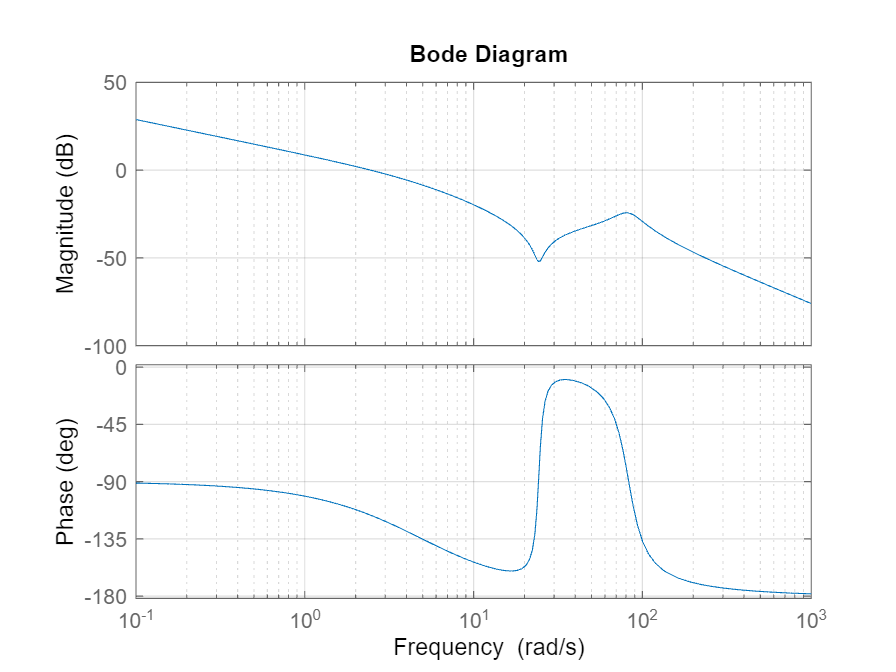

% Get magnitue and phase at the desired frequency
bode(P)
grid on

[magPwg, phasePwg] = bode(P, perf.wg)

magPwg = 0.1065

phasePwg = -152.9900

dK = abs(magPwg)^-1;
dPh = -pi + perf.phi*deg2rad - phasePwg*deg2rad;

pid.a = 4;                 
pid.K = dK * cos(dPh);
Td = (tan(dPh)+sqrt(tan(dPh)^2+4/pid.a))/(2*perf.wg);
Ti = pid.a*Td;

pid.Kd = pid.K*Td;
pid.Ki = pid.K/Ti;
disp(pid)

     a: 4
     K: 9.1789
    Kd: 0.5755
    Ki: 36.6016



Determine real derivative paramters for the PID

der.Tl = 1/(10*perf.wg);

Determine anti-windup parameters

awu.Tw = perf.ts5/5;
awu.Kw = 1/awu.Tw;

Simulations for the PID

simul.stepdeg = 50;
PID.deg_50 = sim('PID_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
simul.stepdeg = 120;
PID.deg_120 = sim('PID_Real','StartTime','0','StopTime','10','AlgebraicLoopMsg', 'off');
save('PID.mat','PID');

## **2.3 STATE SPACE CONTROL**

#### NOMINAL STATE SPACE

ss_nominal.wn = perf.wg;
ss_nominal.d = perf.d;
ss_nominal.phi = atan(sqrt(1-ss_nominal.d^2)/perf.d);
%ss_nominal.poles = [ss_nominal.wn*exp(1j*(pi+ss_nominal.phi)) ss_nominal.wn*exp(1j*(pi-ss_nominal.phi)) ss_nominal.wn*exp(1j*(pi+ss_nominal.phi/2)) ss_nominal.wn*exp(1j*(pi-ss_nominal.phi/2))];
ss_nominal.poles =[-20-10*1i -20+10*1i -30-10*1i -30+10*1i];
ss_nominal.K = real(place(SS.A, SS.B, ss_nominal.poles));
ss_nominal.N = [SS.A SS.B; SS.C SS.D]\[zeros(4,1); 1];
ss_nominal.Nx = ss_nominal.N(1:4);
ss_nominal.Nu = ss_nominal.N(5);


